# enae301 hw08 - p8.10

## part b

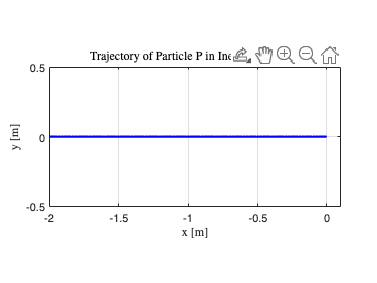

v0 = 1;
t_end = 2;
t = linspace(0, t_end, 100);

x0 = 0;
y0 = 0;

x_inertial = x0 - v0 * t;  % x(t) = -v0 * t
y_inertial = y0 + 0 * t;   % y(t) = 0

figure;
plot(x_inertial, y_inertial, 'b-', 'LineWidth', 2);
xlabel('x [m]', Interpreter='latex');
ylabel('y [m]', Interpreter='latex');
title('Trajectory of Particle P in Inertial Frame \(\mathcal{I}\)', Interpreter='latex');
grid on;
axis equal;
xlim([-2, 0.1]);
ylim([-0.5, 0.5]);

## part d

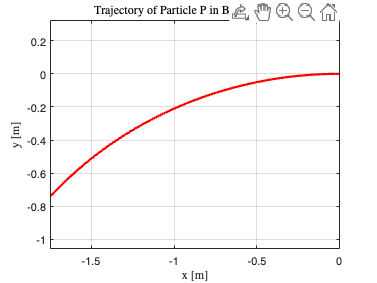

Omega = 0.2;
t_span = [0 t_end];

dx0 = -v0;
dy0 = 0;
u0 = [x0; y0; dx0; dy0];

[t_body, u_body] = ode45(@odefun, t_span, u0);

x_body = u_body(:,1);
y_body = u_body(:,2);

figure;
plot(x_body, y_body, 'r-', 'LineWidth', 2);
xlabel('x [m]', Interpreter='latex');
ylabel('y [m]', Interpreter='latex');
title('Trajectory of Particle P in Body Frame \(\mathcal{B}\)', Interpreter='latex');
grid on;
axis equal;

function du_dt = odefun(t, u)
    Omega = 0.2;

    % ODE
    x = u(1);
    y = u(2);
    dx = u(3);
    dy = u(4);
    du_dt = zeros(4,1);
    du_dt(1) = dx;
    du_dt(2) = dy;
    du_dt(3) = -2 * Omega * dy - Omega^2 * x;
    du_dt(4) =  2 * Omega * dx - Omega^2 * y;
end